# Logistic Regression Algorithm

In this exercice we're going to implement a classification model using logistic regression and regularized logistic regression. First, we're going to use logistic regression for binary classification, and then we're going to implement the one-vs-all classification technique using regularized logistic regression.

This exercice is inspired from the Machine Learning course by Andrew Ng [1]

## Import Data

First we're going to load tthe data we're going to use in this exercice:

clf
clear
load x1.dat
load x2.dat
load y.dat

## Data visualization

Visualizing the data is an important step when we're applying any regression method, because it give us an idea about the distribution of our data, and thus we can have a first thought about what type of regression and how to chose certain parameters.

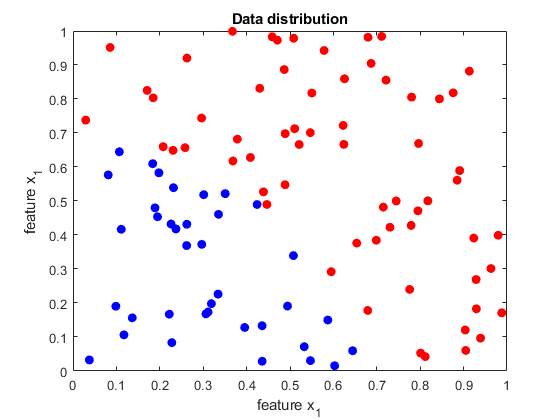

pos=find(y==1);
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
xlabel('feature x_1');
ylabel('feature x_1');
title('Data distribution');
hold off

## Hypothesis function

The first step is to define our hypothesis function:


$$h_\theta(x)=g(\theta^T X)=\frac{1}{1+e^{-\theta^T X}}$$


The hypothesis function is defined in the file hyp.m, and the sigmoid function in the file sigmoid.m

### Visualization of the Sigmoid function:

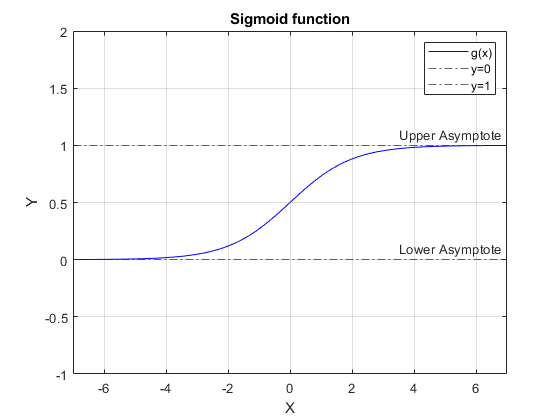

temp_x=-7:0.1:7;
temp_y=sigmoid(temp_x);

plot(temp_x,temp_y,'b-');
hold on
yline(0,'-.','Lower Asymptote');
yline(1,'-.','Upper Asymptote');
xlabel('X');
ylabel('Y');
title('Sigmoid function');
xlim([-7 7]);
ylim([-1 2]);
grid on
legend('g(x)','y=0','y=1')
hold off

## Cost function

The cost function and it's partial derivative with respect to theta is defined as follow:


$$J(\theta)=-\frac{1}{m}\left[ \sum\limits_{i=1}^m y^{(i)}\log(h_\theta(x^{(i)}))+(1-y^{(i)})\log(1-h_\theta(x^{(i)}))\right]$$



$$\frac{\partial J}{\partial \theta_0}=\frac{1}{m}\sum\limits_{i=1}^m(h_\theta(x^{(i)})-y^{(i)})$$



$$\frac{\partial J}{\partial \theta_j}=\frac{1}{m}\sum\limits_{i=1}^m(h_\theta(x^{(i)})-y^{(i)})x_j^{(i)}$$


Here we're going to define the cost function LogCost.m

This function returns both the value of  the cost function J on theta and also, the value of the derivative of J on theta.

X=[ones(length(y),1) x1' x2'];
lambda=0;
theta=zeros(size(X,2),1);

### Initial value test

[j,gradient]=LogCost(theta,X,y,lambda)

j = 0.6931

gradient =    -0.1300
   -0.1380
   -0.1356


## Advanced optimization

In this section we're going to solve the optimization problem using an advanced technique provided by matlab instead of implementing gradient descent manually.

options = optimset('GradObj', 'on', 'MaxIter', 100);
initialTheta = theta;
[optTheta, functionVal, exitFlag] = fminunc(@(t)(LogCost(t, X, y,lambda)), initialTheta, options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


optTheta =   -23.3125
   28.1910
   27.1009


functionVal = 0.1053

exitFlag = 1

### Plotting of the decision boundary

The green line represent the decision boundary that separates the two classes 1 and 0.

The equation of the line is:


$$y=-\frac{-\theta_0}{\theta_1}-\frac{\theta_2}{\theta_1}x$$


Where theta is the solution of our optimization problem.

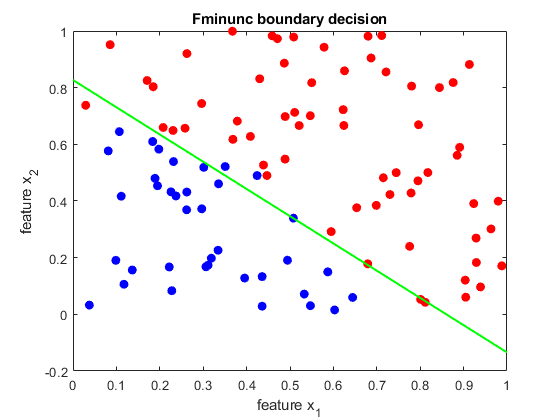

temp_x=0:0.1:1;
Db=-optTheta(1)/optTheta(2)-optTheta(3)/optTheta(2)*temp_x;
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
plot(temp_x,Db,'g-','LineWidth',1.5)
xlabel('feature x_1');
ylabel('feature x_2');
title('Fminunc boundary decision');
hold off

## Gradient Descent

Now, we're going to solve our minimization problem using the gradient descent algorithm, and then compare the results with those obtained using the fminun matlab function.

max_it=10000;
alpha=10;
[theta_op,Theta,J]=GradDesc(alpha,X,y,max_it)

theta_op =   -23.2561
   28.1251
   27.0340


Theta =          0    1.3000   -1.6729    2.1553   -1.4451   -1.3562   -2.2325   -1.3624   -3.1569   -1.0557   -3.7795   -1.5572   -4.1710   -2.3031   -4.4787   -2.9013   -4.6879   -3.4376   -4.8233   -3.9053   -4.9141   -4.3034   -4.9903   -4.6344   -5.0748   -4.9058   -5.1783   -5.1294   -5.3004   -5.3183   -5.4344   -5.4843   -5.5731   -5.6356   -5.7115   -5.7773   -5.8468   -5.9122   -5.9780   -6.0418   -6.1049   -6.1667   -6.2276   -6.2874   -6.3464   -6.4044   -6.4615   -6.5177   -6.5731   -6.6277
         0    1.3802    0.5571    3.1396    2.0426    2.5305    2.5240    3.3324    2.8809    4.2778    3.4459    4.8556    4.0461    5.2192    4.5505    5.5361    4.9975    5.7879    5.3900    5.9943    5.7341    6.1749    6.0360    6.3462    6.3018    6.5181    6.5376    6.6931    6.7497    6.8695    6.9440    7.0443    7.1253    7.2151    7.2969    7.3807    7.4609    7.5407    7.6185    7.6952    7.7704    7.8444    7.9172    7.9888    8.0592    8.1285    8.1968    8.2641    8.3303 

J =     0.6931    0.8617    0.9139    1.4980    0.4314    0.4161    0.4151    0.4544    0.4848    0.6462    0.4738    0.6016    0.4118    0.4720    0.3660    0.3884    0.3235    0.3249    0.2882    0.2814    0.2619    0.2544    0.2445    0.2389    0.2336    0.2298    0.2265    0.2237    0.2212    0.2189    0.2167    0.2147    0.2127    0.2109    0.2091    0.2073    0.2057    0.2041    0.2025    0.2010    0.1996    0.1982    0.1968    0.1955    0.1942    0.1930    0.1918    0.1906    0.1895    0.1884


### Plottting of the evolution of J with respect to each iteration

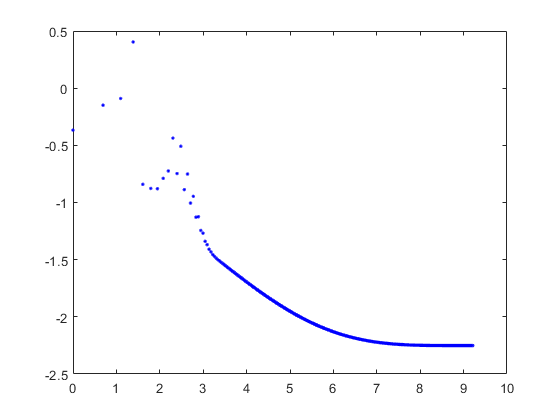

figure(1)
x_axis=1:length(J);
plot(log(x_axis),log(J),'.b')
hold off

### Plotting of the evolution of the decision boundary

Since the matlab live script doesn't support dynamic figures yet, we can add the command: figure('visible','on) to make the figure pop up in a window and thus we can see the evolution dynamically.

In case, we don't add the cited command, we only see the last iteration of the evolution which represent the decision boundary with the optimal theta obtained using the gradient descent algorithm.

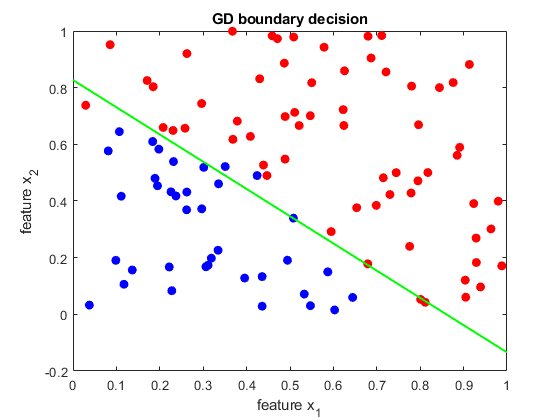

figure(2)
%figure('visible','on')
for i=1:3:length(Theta)
xlabel('feature x_1');
ylabel('feature x_2');
title('Data distribution');
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
Db=-Theta(1,i)/Theta(2,i)-Theta(3,i)/Theta(2,i)*temp_x;
plot(temp_x,Db,'g-','LineWidth',1.5)
pause(0.01)
hold off
end
xlabel('feature x_1');
ylabel('feature x_2');
title('GD boundary decision');

The error between the optimal theta calculated using GD and the one calculated using fminunc is the folowing:

Error=norm(theta_op-optTheta);
s=sprintf('The RMSE error between GD and fminunc estimations is:%f',Error);
disp(s)

The RMSE error between GD and fminunc estimations is:0.109550


We can reduce this error by adding more iterations to the GD loop, or adjusting the learning rate.

# One-Vs-All Classification

In this part we're going to implement the (non-binary) classification (3 classes), however to achieve that we're only using binary classification algorithms.

The key idea is define a decision boundary for each couple of classes then to predict a certain enrty belongs to which class, we take the max of the 3 probabilites determined in the class coupling step.

## Loading data

We're going to use the same data set as in the binary classification above, but this time they are mapped to 3 classes.

clf
clear
load x1.dat
load x2.dat
load multi_y.dat

The x1 and x1 data are generated randomly in the interval [0,1] using the rand function. The class assignment y(i) for each couple (x1(i),x2(i)) is determined such that:

1st Class y=0: Points that are inside of the circle C1 centered in (0,0) and of radius 0.5

2nd Class y=1: Points that are inside of the circle C2  centered in (0,0) and of radius 1 and outside the circle C1

3d Class y=3: The rest of the points

### Visualizing the data set

Here we can see the distribution of our dataset, with the 3 different classes.

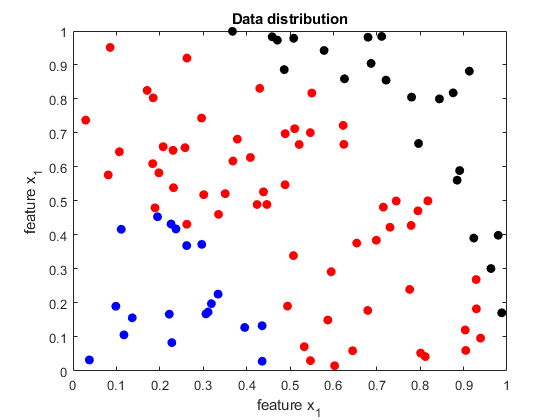

pos=find(multi_y==1);
pos2=find(multi_y==2);
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
plot(x1(pos2),x2(pos2),'ok','MarkerFaceColor','k');
xlabel('feature x_1');
ylabel('feature x_1');
title('Data distribution');
hold off

## Data preparation

First, we need to prepare our data sets to be ready to make 3 binary classifications. 

First class couple (y=0,others):

y_c1=multi_y;
y_c1(pos2)=1;

Second class couple (y=2,others):

y_c2=multi_y;
y_c2(pos)=0;
y_c2(pos2)=1;

Third class couple (y=1,others)

y_c3=multi_y;
y_c3(pos2)=0;

Visulaization of the three binary classification datasets:

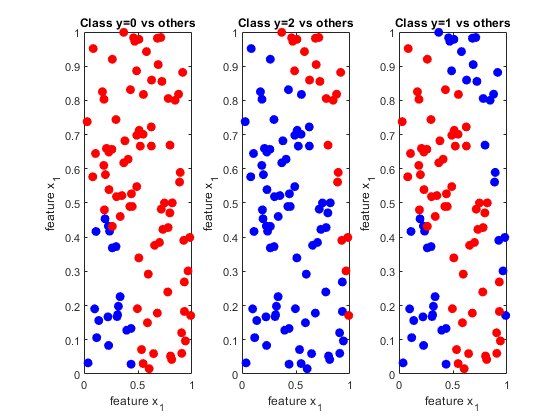

subplot(1,3,1)
pos=find(y_c1==1);
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
xlabel('feature x_1');
ylabel('feature x_1');
title('Class y=0 vs others');
hold off
subplot(1,3,2)
pos=find(y_c2==1);
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
xlabel('feature x_1');
ylabel('feature x_1');
title('Class y=2 vs others');
hold off
subplot(1,3,3)
pos=find(y_c3==1);
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
xlabel('feature x_1');
ylabel('feature x_1');
title('Class y=1 vs others');
hold off

## Optimization

In this section we're going to perform the logistic regression for each class couple, using both gradient descent and fminunc, the results for each binary classification is represented in the correspondent figure. 

***Notice:*** When applying the Log.Reg. for a couple of classes we need to set their y value to 0 for one class and 1 for the other. In case, we set it to 0 for one class and 2 to the other class, a certain numeric problem occures and we wouldn't be able to find a minimizer for the cost function.

Initialization of the some variables:

X=[ones(length(multi_y),1) x1' x2'];
theta=zeros(size(X,2),1);
lambda=0;

#### Class couple (y=0, others)

Grad descent and fminunc implemetaion:

max_it=3000;
alpha=15;
[theta_op,Theta,J]=GradDesc(alpha,X,y_c1,max_it)

theta_op =   -22.0722
   38.7281
   30.7527


Theta =          0    4.6500    1.8131   -0.7096    0.4939   -1.5051    0.4554   -1.8451   -0.5859   -2.3073   -0.8964   -2.6112   -1.3889   -2.8486   -1.8287   -3.0309   -2.2245   -3.1722   -2.5770   -3.2875   -2.8861   -3.3912   -3.1526   -3.4951   -3.3800   -3.6059   -3.5742   -3.7247   -3.7425   -3.8489   -3.8923   -3.9746   -4.0291   -4.0989   -4.1569   -4.2200   -4.2781   -4.3371   -4.3939   -4.4502   -4.5051   -4.5593   -4.6124   -4.6646   -4.7160   -4.7665   -4.8163   -4.8652   -4.9134   -4.9609
         0    3.0572    2.3556    1.7675    2.7800    2.3691    3.6341    3.0952    3.9543    3.5950    4.4660    4.0917    4.8378    4.5349    5.1636    4.9354    5.4523    5.3004    5.7144    5.6351    5.9592    5.9430    6.1934    6.2265    6.4212    6.4881    6.6441    6.7309    6.8618    6.9579    7.0735    7.1724    7.2785    7.3766    7.4764    7.5722    7.6675    7.7604    7.8521    7.9420    8.0306    8.1177    8.2034    8.2878    8.3710    8.4529    8.5337    8.6133    8.6918 

J =     0.6931    1.1576    0.5800    0.3604    0.4053    0.3577    0.4508    0.2984    0.3274    0.2868    0.3150    0.2646    0.2783    0.2456    0.2499    0.2293    0.2283    0.2158    0.2126    0.2052    0.2017    0.1971    0.1941    0.1911    0.1887    0.1864    0.1844    0.1826    0.1808    0.1792    0.1776    0.1761    0.1747    0.1733    0.1720    0.1708    0.1696    0.1684    0.1673    0.1662    0.1651    0.1641    0.1631    0.1622    0.1612    0.1603    0.1595    0.1586    0.1578    0.1570


options = optimset('GradObj', 'on', 'MaxIter', 10000);
initialTheta = theta;
[optThetac1, functionVal, exitFlag] = fminunc(@(t)(LogCost(t, X, y_c1,lambda)), initialTheta, options)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


optThetac1 =   -20.6130
   32.6290
   31.2408


functionVal = 0.1014

exitFlag = 5

Plotting of figures:

Plotting of the boundary decision for the first class couple:

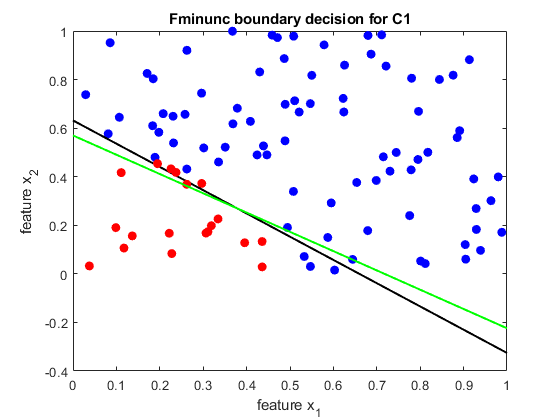

temp_x=0:0.1:1;
figure(5)
pos=find(y_c1==0);
Db=-theta_op(1)/theta_op(2)-theta_op(3)/theta_op(2)*temp_x;
Db2=-optThetac1(1)/optThetac1(2)-optThetac1(3)/optThetac1(2)*temp_x;
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(temp_x,Db2,'k-','LineWidth',1.5)
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
plot(temp_x,Db,'g-','LineWidth',1.5)
xlabel('feature x_1');
ylabel('feature x_2');
title('Fminunc boundary decision for C1');
hold off

Plotting of the evolution of the value of the natural log of the cost function J as a function of G.D. iterations.

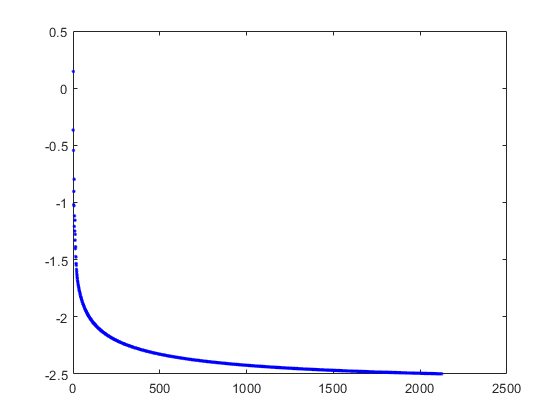

figure(6)
x_axis=1:length(J);
plot(x_axis,log(J),'.b');
hold off

#### Class couple (y=2, others)

max_it=10000;
alpha=70;
[theta_op,Theta,J]=GradDesc(alpha,X,y_c2,max_it)

theta_op =   -82.1378
   66.6535
   52.7318


Theta =          0  -19.6000   -4.2000  -36.7577  -21.3577   -5.9577  -53.3933  -37.9933  -22.5933  -11.5053  -57.7075  -42.3075  -26.9075  -35.9498  -20.5683  -57.6782  -42.2782  -26.9362  -58.3163  -42.9163  -34.9507  -51.4806  -36.0809  -54.0369  -38.6371  -53.6241  -38.2449  -58.8322  -43.4323  -54.6973  -40.9874  -61.6082  -46.2089  -57.8270  -44.9914  -62.0695  -46.8736  -63.0161  -48.3464  -64.2989  -50.0410  -65.0390  -51.8593  -65.1667  -53.5649  -65.2084  -54.8769  -65.5642  -55.6787  -66.0749
         0   -6.2653    5.0298  -10.7007    0.5944   11.8894  -10.1777    1.1174   12.4125   20.5093   -1.1695   10.1256   21.4206   16.3651   27.6447    9.1546   20.4497   31.6949   15.1700   26.4651   32.3663   22.7965   34.0913   23.7845   35.0795   26.2748   37.5515   25.8215   37.1165   30.3154   40.2247   28.4769   39.7715   32.7400   41.9767   32.1554   43.2684   33.8991   44.5580   35.2752   45.6046   36.7680   46.2649   38.2299   46.5252   39.3783   46.7565   40.2275   47.2975 

J =     0.6931    6.2360    1.0252   11.4916    4.3202    3.9580   14.7489    7.5774    0.5061    5.9529   12.5882    5.4167    0.3972    2.0788    4.8021    9.2299    2.0593    3.8361    7.2588    0.4782    1.2843    3.3552    1.5191    3.5730    1.2085    2.6370    2.0690    3.8781    0.8329    1.5185    2.2138    3.5662    0.9443    1.3908    1.7199    2.4698    1.6372    2.1067    1.6570    1.9399    1.5614    1.6373    1.3519    1.2673    1.1018    1.0207    0.9176    0.9375    0.8543    0.9143


options = optimset('GradObj', 'on', 'MaxIter', 1000);
initialTheta = theta;
[optThetac2, functionVal, exitFlag] = fminunc(@(t)(LogCost(t, X, y_c2,lambda)), initialTheta, options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


optThetac2 =   -39.2534
   32.9707
   26.2631


functionVal = 0.0965

exitFlag = 1

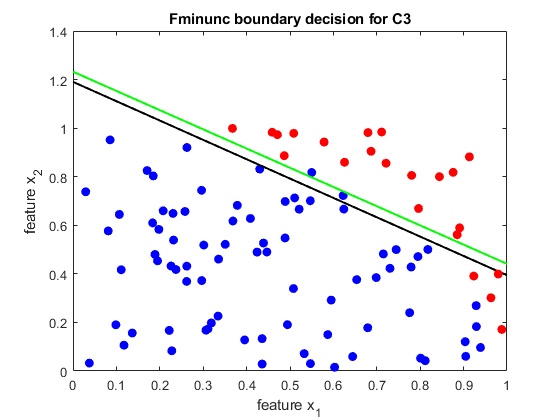

temp_x=0:0.1:1;
figure(7)
pos=find(y_c2==1);
Db=-theta_op(1)/theta_op(2)-theta_op(3)/theta_op(2)*temp_x;
Db2=-optThetac2(1)/optThetac2(2)-optThetac2(3)/optThetac2(2)*temp_x;
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(temp_x,Db2,'k-','LineWidth',1.5)
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
plot(temp_x,Db,'g-','LineWidth',1.5)
xlabel('feature x_1');
ylabel('feature x_2');
title('Fminunc boundary decision for C3');
hold off

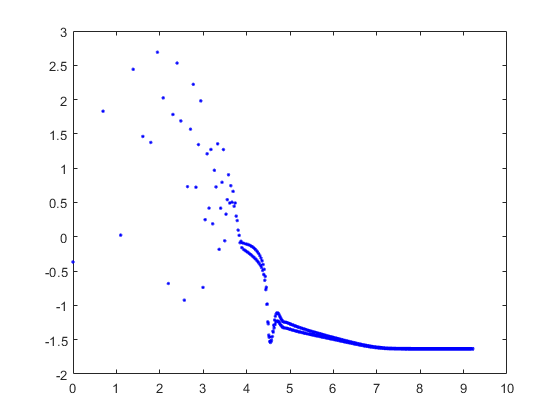


figure(8)
x_axis=1:length(J);
plot(log(x_axis),log(J),'.b');
hold off

#### Class couple (y=1, others)

For this dataset, we are unable to use a line as a boundary decision because the data were y=1 is in the middle of the other data y=0. So, one solution here is to add more degrees to the boundary decision equation, which is the same as adding more features.

Previous cases:


$$\theta^TX=\theta_0+\theta_1x_1+\theta_2x_2$$


This case:


$$\theta^TX=\theta_0+\theta_1x_1+\theta_2x_2+\theta_3x_1x_2+\theta_4x_1^2+\theta_5x_2^2+...$$


However, adding too many features may result in an over-fitting problem which is a famous problem in machine learning. So, to avoid overfitting, we're going to use a method called L2 regularization.

According to Ian Goodfellow [2]

*“Regularization is any modification we make to a learning algorithm that is intended to reduce its generalization error but not its training error.”*

L2 Regularization method is consist in addinng a regularizing term which is the weighted L2 norm of the weights vector Theta:


$$\mbox{L2 Norm: }\parallel \theta\parallel_{2}=\sqrt{\sum_{i=0}^n \theta_i^2} $$



$$\mbox{Regularizing term: } \frac{\lambda}{2m}\parallel\theta\parallel_2^2$$


Thus, the cost function becomes:


$$J(\theta)=-\frac{1}{m}\sum_{i=1}^m\left[ y^{(i)}\log(h_\theta(x^{(i)}))+(1-y^{(i)})\log(1-h_\theta(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n \theta_j^2$$



$$\mbox{where: } m=\mbox{Nbr. training examples}\\
\qquad \quad n=\mbox{Nbr. features}\\
\qquad \quad \lambda=\mbox{Regularization coefficient}$$


Seperating the features in vectors: 

X1=X(:,2);
X2=X(:,3);

Using the feature vectors to generate new features, and initializing some variables for the optimization algorithm:

degree = 5; % always consider all the monomes of the polynome of a certain degree
out = ones(size(X1(:,1)));
for ii = 1:degree
    for jj = 0:ii
        out(:, end+1) = (X1.^(ii-jj)).*(X2.^jj);
    end
end
Xplus=out;
%Xplus=[X X1.^2 X1.*X2 X2.^2];
theta=zeros(size(Xplus,2),1);
lambda=0;

The choice of the value of lambda depends on the degree of the features polynomial that we're using. A higher degree requires a higher regularization coefficient in order to avert the overfitting scenario.

Determination of the optimized value of theta using the fminunc:

options = optimset('GradObj', 'on', 'MaxIter', 1000);
initialTheta = theta;
[opThe3, functionVal, exitFlag] = fminunc(@(t)(LogCost(t, Xplus, y_c3,lambda)), initialTheta, options)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


opThe3 =  -101.6487
  150.7669
  120.1355
   90.6489
   -9.3550
   91.1754
    9.5938
  -52.5273
  -46.7537
   23.4055


functionVal = 0.0189

exitFlag = 5

Plotting of the boundary decision for the third class couple:

Since we're using a high order polynomial as a decision boundary then to plot it for our dataset (x1,x2) we're going to plot the countour line that correspond to the z=0 level, in other words the curve defined by:


$$\theta^TX=0$$


The decision boundary is presented by the discontinuous black line on the following figure:

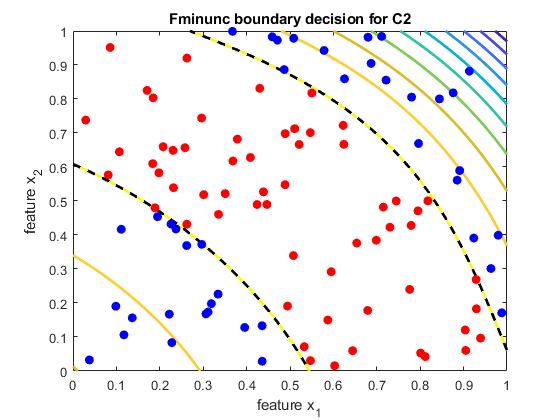

temp_x=0:0.1:1;
figure(9)
pos=find(y_c3==1);
plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
u = linspace(0, 1, 100);
    v = linspace(0, 1, 100);

    z = zeros(length(u), length(v));
    % Evaluate z = theta*x over the grid
    for i = 1:length(u)
        for j = 1:length(v)
            
            X1=u(i); X2=v(j);
out = ones(size(X1(:,1)));
for ii = 1:degree
    for jj = 0:ii
        out(:, end+1) = (X1.^(ii-jj)).*(X2.^jj);
    end
end
            z(i,j) = out*opThe3;
        end
    end
    z = z'; % important to transpose z before calling contour

    % Plot z = 0
    % Notice you need to specify the range [0, 0]
    contour(u, v, z, 'LineWidth', 2)
    contour(u, v, z, [0, 0],'--k', 'LineWidth', 2)


plot(x1,x2,'ob','MarkerFaceColor','b');
hold on
plot(x1(pos),x2(pos),'or','MarkerFaceColor','r');
xlabel('feature x_1');
ylabel('feature x_2');
title('Fminunc boundary decision for C2');
hold off

### Test

In this final part, we're going to use our one-vs-all logistic regression model to estimate the classes of 100 example and compute the accuracy of our model

Loading test data

load test_x1.dat
load test_x2.dat
load test_y.dat

Visualization of the test dataset:

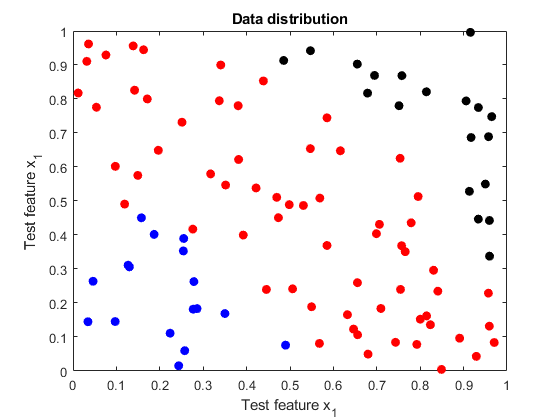

pos=find(test_y==1);
pos2=find(test_y==2);
plot(test_x1,test_x2,'ob','MarkerFaceColor','b');
hold on
plot(test_x1(pos),test_x2(pos),'or','MarkerFaceColor','r');
plot(test_x1(pos2),test_x2(pos2),'ok','MarkerFaceColor','k');
xlabel('Test feature x_1');
ylabel('Test feature x_1');
title('Data distribution');
hold off

Applying our classification model:

pred_c1=1-sigmoid(optThetac1(1)+optThetac1(2).*test_x1+optThetac1(2).*test_x2);
pred_c2=sigmoid(optThetac2(1)+optThetac2(2).*test_x1+optThetac2(2).*test_x2);

test_out = ones(size(test_x1(:,1)));
for ii = 1:degree
    for jj = 0:ii
        test_out(:, end+1) = (test_x1.^(ii-jj)).*(test_x2.^jj);
    end
end
pred_c3=sigmoid(test_out*opThe3);

pred_M=[pred_c1 pred_c3 pred_c2];
pred_y=zeros(size(pred_M,1),1);
for t=1:length(pred_y)
    [~,pred_y(t)]=max(pred_M(t,:));
end
pred_y=pred_y-1;

Test_result= test_y==pred_y;
Model_accuracy=(sum(Test_result)/length(Test_result))*100;
fprintf('This model made %d right classification and %d wrong classification.',...
       sum(Test_result),length(Test_result)-sum(Test_result));

This model made 97 right classification and 3 wrong classification.

fprintf('The one-vs-all model accuracy is %.1f%%',Model_accuracy)

The one-vs-all model accuracy is 97.0%

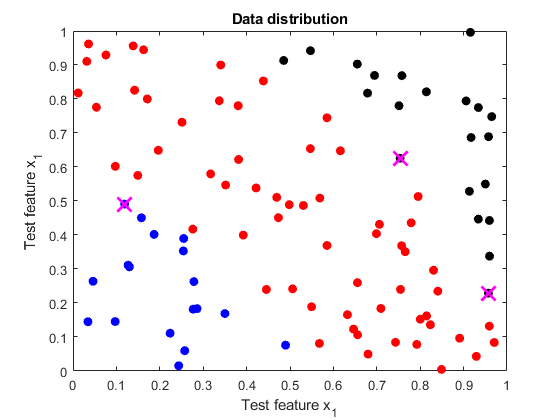


pos_wrong= find(Test_result==0);

pos=find(pred_y==1);
pos2=find(pred_y==2);
plot(test_x1,test_x2,'ob','MarkerFaceColor','b');
hold on
plot(test_x1(pos),test_x2(pos),'or','MarkerFaceColor','r');
plot(test_x1(pos2),test_x2(pos2),'ok','MarkerFaceColor','k');
plot(test_x1(pos_wrong),test_x2(pos_wrong),'xm',"MarkerSize",15,"LineWidth",2);
xlabel('Test feature x_1');
ylabel('Test feature x_1');
title('Data distribution');
hold off

### References:

[1] Andrew Ng: [https://www.andrewng.org/](https://www.andrewng.org/)

[2] Ian Goodfellow, Yushua Bengio, Aaron Courville, “Deep Learning”, London: The MIT Press, 2017.